# Example 1.1: Noisy Flow Sensors

Note: this script reproduces Example 1.1 (Section 1.1) of **Statistics for Chemical Engineers**: three flow sensors measure the flows of a mixer, and mass conservation says that f3 = f1 + f2. Victor Z UW-Madison, 2020 flow sensor example

clc; clear all; close all hidden;

## Simulate the sensor readings

Note: each sensor reports the true flow plus a random error (precision of about 1%). generate data for three flows

rng(0)
N=100;
time=0:1:N-1;
F1 = normrnd(100,100*0.01/2.5,N,1);
F2 = normrnd(50,50*0.01/2.5,N,1);
F3 = normrnd(150,150*0.01/2.5,N,1);

## Conservation error

Note: if the sensors were exact, the error f3 - f2 - f1 would always be zero. compute conservation error

err = F3-F2-F1;

## Sensor readings

Note: the readings fluctuate randomly around the true flows and stay mostly within the 1% bands. visualize flows

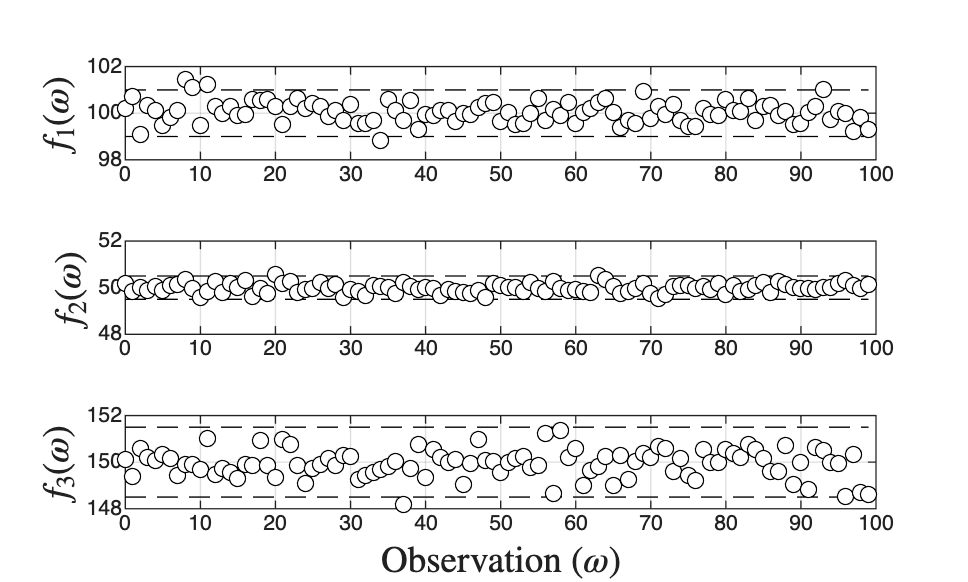

figure(1)
subplot(3,1,1)
plot(time,100*1.01*ones(N),'black--')
hold on
plot(time,100*0.99*ones(N),'black--')
plot(time,F1,'blacko','MarkerFaceColor','w')
ylabel('$f_1(\omega)$','Interpreter','latex','FontSize',14)
grid on
axis([0 N 98 102])
subplot(3,1,2)
plot(time,50*1.01*ones(N),'black--')
hold on
plot(time,50*0.99*ones(N),'black--')
plot(time,F2,'blacko','MarkerFaceColor','w')
ylabel('$f_2(\omega)$','Interpreter','latex','FontSize',14)
grid on
axis([0 N 48 52])
subplot(3,1,3)
plot(time,150*1.01*ones(N),'black--')
hold on
plot(time,150*0.99*ones(N),'black--')
plot(time,F3,'blacko','MarkerFaceColor','w')
xlabel('Observation ($\omega$)','Interpreter','latex','FontSize',14)
ylabel('$f_3(\omega)$','Interpreter','latex','FontSize',14)
grid on
axis([0 N 148 152])
print -depsc ch1_mixer_flows.eps

## Error over time

Note: the error has no trend; it fluctuates randomly around zero. visualize conservation error

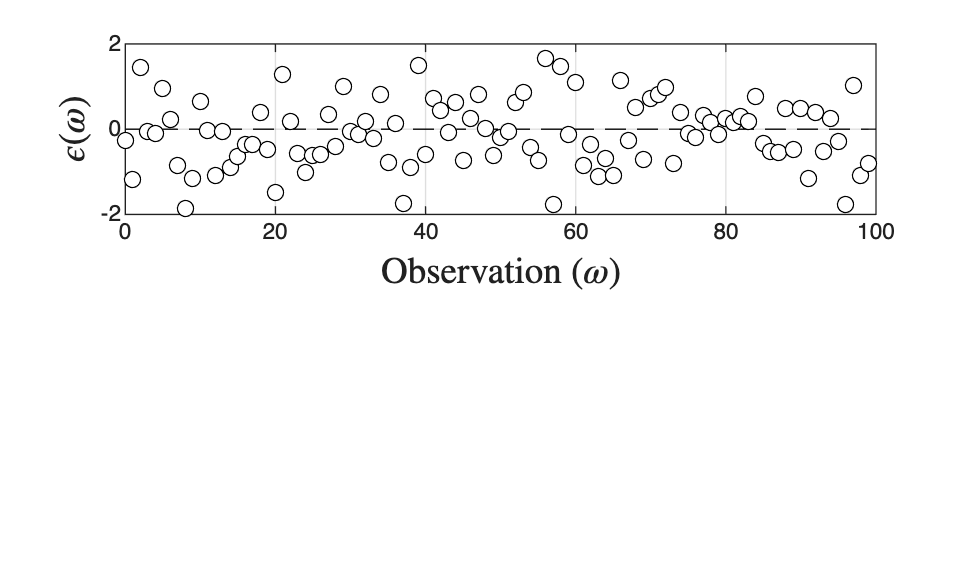

figure(2)
subplot(2,1,1)
plot(time,0*ones(N),'black--')
hold on
plot(time, err,'blacko','MarkerFaceColor','w')
grid on
xlabel('Observation ($\omega$)','Interpreter','latex','FontSize',14)
ylabel('$\epsilon(\omega)$','Interpreter','latex','FontSize',14)
print -depsc ch1_mixer_flows_error.eps

## Note

As in the book, the mismatch in mass conservation comes from random sensor errors, not from a flaw in the conservation law. Enough data is needed to see this, and both engineering knowledge (conservation) and data are needed to understand the system.